clc
clear all
close all

%loading data
load('Received.mat')

25 m depth reciever


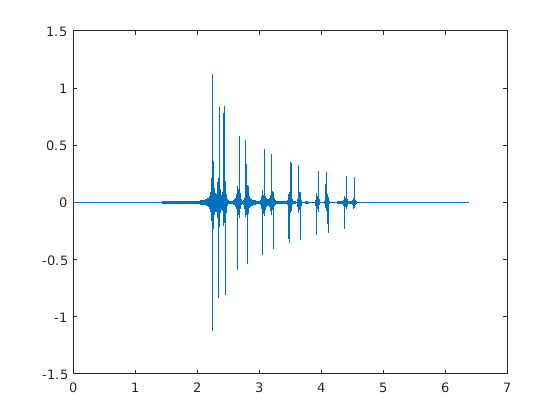

50 m depth reciever


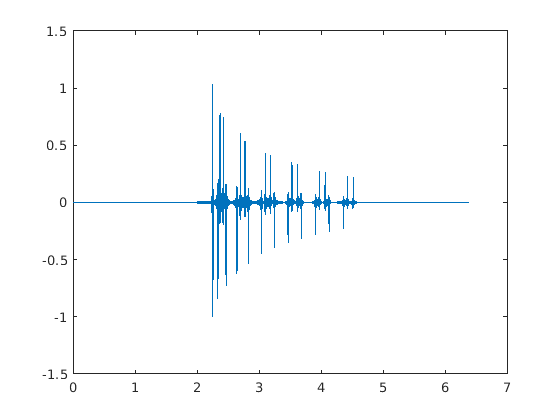

75 m depth reciever


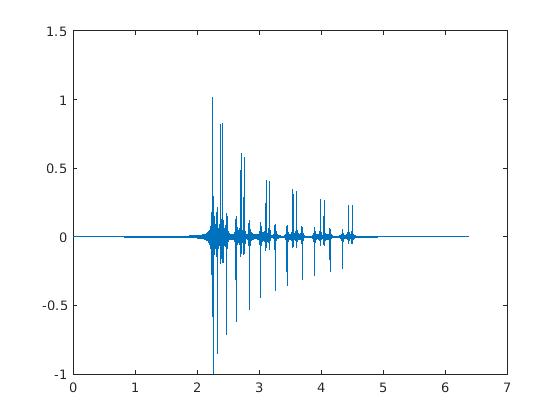

100 m depth reciever


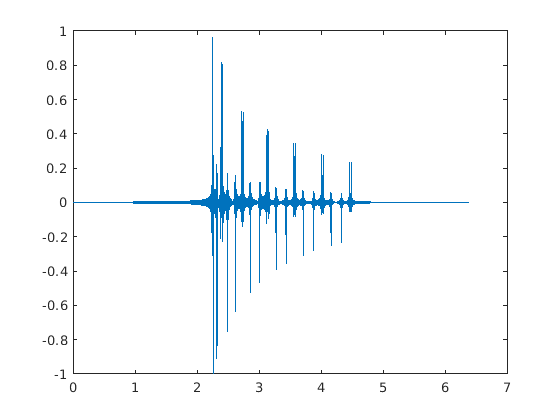

125 m depth reciever


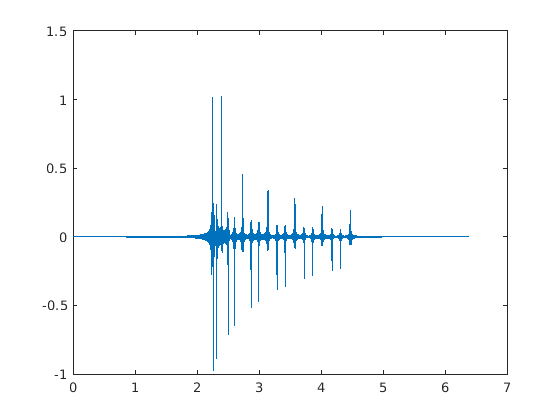

150 m depth reciever


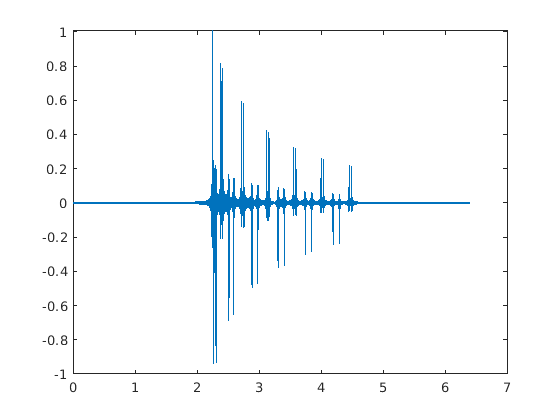

175 m depth reciever


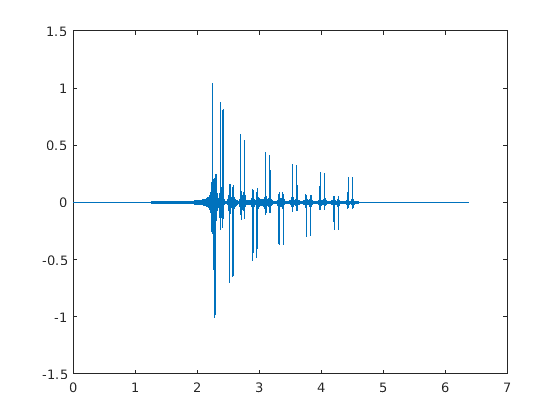

200 m depth reciever


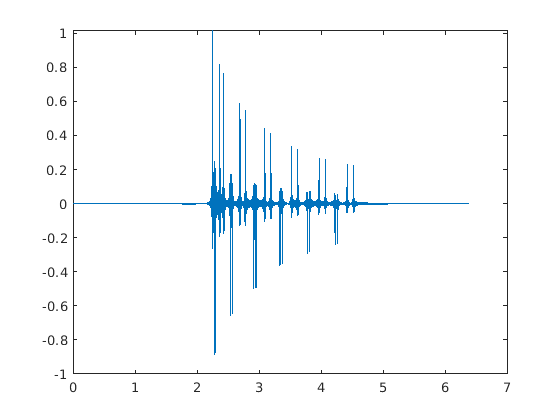

225 m depth reciever


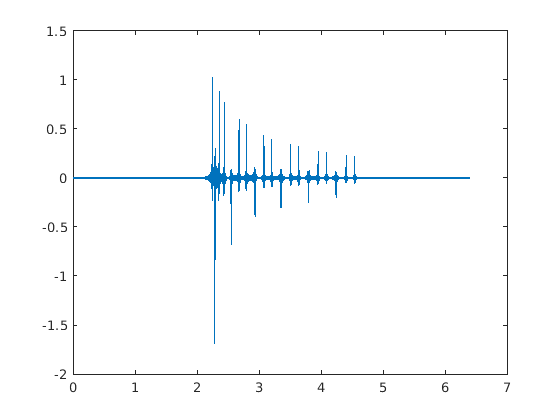

t = 1:32000;
t = t*2e-4;
for i =1:9
    disp(sprintf('%d m depth reciever', i*25))
    figure()
    plot(t,RecSig(i,:))
    hold off
end

## **The first peak is at 2.2492 secs away. so roughly the source is 2.2492 * 1500 = 3373.**

## **8  m away.**

dt = 2e-4;
fs = 1/dt;
t= dt:dt:6.4;


%coordinate to search for the focusing
all_x_coor = -3500:25:-1500;
all_y_coor = 15:15:350;
t = -6.4+dt:dt:6.4;
energy_values = zeros(size(all_x_coor, 2),size(all_y_coor, 2));
ii = 0;
for i = all_x_coor
    ii = ii+1;
    jj= 0;
    i
    for j=all_y_coor
        jj = jj+1;
        
        all_zs =  [1:9]*25; %recievers pos z
        %all_R = [];
        all_x = zeros(size(t,2),1);
        for z=all_zs 
            R = RecSig(z/25,:)';
            
            R = flip(R);
            new_R = zeros(size(t,2)-size(R,1),1);
            C1 = cat(1,R,new_R); %new padded signal
            
            new_x = green(0,z,i,j,C1,t);
            all_x = all_x + new_x;
            %figure()
            %plot(all_x)
            %all_R = horzcat(all_R,R);
        end
        energy_x = all_x.^2;
        energy_values(ii, jj) = sum(sum(energy_x));
    end
end

i = -3500

i = -3475

i = -3450

i = -3425

i = -3400

i = -3375

i = -3350

i = -3325

i = -3300

i = -3275

i = -3250

i = -3225

i = -3200

i = -3175

i = -3150

i = -3125

i = -3100

i = -3075

i = -3050

i = -3025

i = -3000

i = -2975

i = -2950

i = -2925

i = -2900

i = -2875

i = -2850

i = -2825

i = -2800

i = -2775

i = -2750

i = -2725

i = -2700

i = -2675

i = -2650

i = -2625

i = -2600

i = -2575

i = -2550

i = -2525

i = -2500

i = -2475

i = -2450

i = -2425

i = -2400

i = -2375

i = -2350

i = -2325

i = -2300

i = -2275

i = -2250

i = -2225

i = -2200

i = -2175

i = -2150

i = -2125

i = -2100

i = -2075

i = -2050

i = -2025

i = -2000

i = -1975

i = -1950

i = -1925

i = -1900

i = -1875

i = -1850

i = -1825

i = -1800

i = -1775

i = -1750

i = -1725

i = -1700

i = -1675

i = -1650

i = -1625

i = -1600

i = -1575

i = -1550

i = -1525

i = -1500

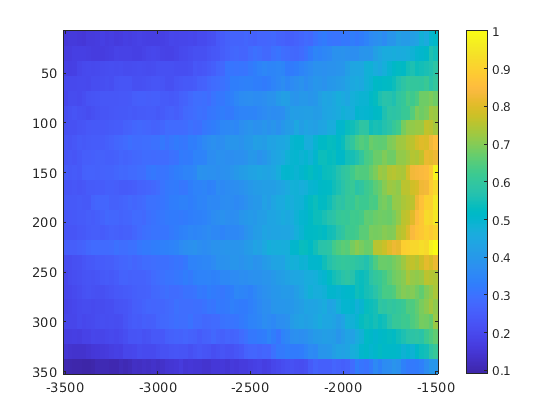

energy_values = energy_values';
image(all_x_coor, all_y_coor,energy_values/(max(max(energy_values))), 'CDataMapping','scaled')
colorbar

%beta = 50;
%signal = sinc(beta.*t)';
%plot(t,signal)
%rcv = green(0,100, 3300, 100, signal, t );
t = -6.4+dt:dt:6.4;
plot(R)
new_R = zeros(size(t,2)-size(R,1),1);
C1 = cat(1,R,new_R);
%flipted_rcv = flip(rcv);
sig = green(0, 100, -3300, 100, C1,t);
plot(sig)

for i = 1:9
    recv_signal = RecSig(i,:);
    reversed_recv_signal = flip(recv_signal);
    plot(t,reversed_recv_signal)
    
    sig = green(3373, i*25, 0, 100, reversed_recv_signal,t);
    figure
    plot(sig)
    break
end

function R = green(xs, zs, x, z,signal, t)
h = 350; %max_height
xs = xs;
zs = zs;
x = x;
z = z;
c = 1500;

dt = 2e-4;
fs = 1/dt;

%fs = 1.0e4;

r0 = sqrt((x-xs)^2 + (z-zs)^2);
this_signal = delayseq(signal,r0/c,fs);
R = this_signal/(4*pi*r0);

for j = -13:13
    if j ==0
        continue
    end
    if rem(j,2)==0
       r = sqrt((x-xs)^2 + (z-zs+j*h)^2);
       eps = 1;
    else
       r = sqrt((x-xs)^2 + (z+zs-(j+1)*h)^2);
       eps = -1;
    end
    this_signal = delayseq(signal,r/c,fs);
    R = R+(eps/(4*pi*r) *this_signal);
end

end


